# Backward Euler, Forward Euler, Steepest Descent, and Condition Number

Name: Marc-Antoine Nadeau

Due Date: 12 April 2024

## Question 1

 You are given the following 3rd order differential equation,

                
$$y^{'''}(t) + 32 y^{''} (t) +61.25 y'(t)  + 37.5 y(t)  = sin(\frac{\pi t} {4})$$


a. Transform the above differential equation into a system of first-order differential equations. **(5 marks)**


$$Let 

\[ x_1(t) = y(t) \]
\[ x_2(t) = y'(t) = x_1'(t) \]
\[ x_3(t) = y''(t) = x_2''(t) \]

We can re-write the equation as:     
 \[ x_{3}'(t_n) + 32x_{3}(t_n) + 61.25x_{2}(t_n) + 37.50x_{1}(t_n) = \sin\left(\frac{\pi t_n}{4}\right) \]

We can then isolate \( x_{3}' \) and we obtain:
\[ x_{3}(t_n)' = -32x_{3}(t_n) - 61.25x_{2}(t_n) - 37.50x_{1}(t_n) + \sin\left(\frac{\pi t_n}{4}\right) \]

These can be rewritten into these equations:

\[
\begin{cases}
x_1' (t_n) = x_2(t_n) \\
x_2' (t_n) = x_3 (t_n)\\
x_3' (t_n) = \sin\left(\frac{\pi t_n}{4}\right)- 37.50x_1(t_n) - 61.25x_2(t_n) - 32x_3 (t_n)
\end{cases}
\]


From this, we can rewrite our system of equations as follows:
$$


                                                    $\left\lbrack \begin{array}{c}
{x_1 }^{\prime } \left(t_n \right)\\
{x_2 }^{\prime } \left(t_n \right)\\
{x_3 }^{\prime } \left(t_n \right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-37\ldotp 50 & -61\ldotp 25 & -32
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \left(t_n \right)\\
x_2 \left(t_n \right)\\
x_3 \left(t_n \right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
\sin \left(\frac{\pi t_n }{4}\right)
\end{array}\right\rbrack$                    (eq. 1)

Namely, we let 

                        
$$X^{\prime } \left(t_n \right)=\left\lbrack \begin{array}{c}
{x_1 }^{\prime } \left(t_n \right)\\
{x_2 }^{\prime } \left(t_n \right)\\
{x_3 }^{\prime } \left(t_n \right)
\end{array}\right\rbrack \;\;A=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-37\ldotp 50 & -61\ldotp 25 & -32
\end{array}\right\rbrack \;\;\;\;X\left(t_n \right)=\left\lbrack \begin{array}{c}
x_1 \left(t_n \right)\\
x_2 \left(t_n \right)\\
x_3 \left(t_n \right)
\end{array}\right\rbrack \;\;\;b\left(t_n \right)=\left\lbrack \begin{array}{c}
0\\
0\\
\sin \left(\frac{\pi t_n }{4}\right)
\end{array}\right\rbrack \;$$


As such, we get: 

                                                                                $X^{\prime } \left(t_n \right)=A\;X\left(t_n \right)+b\left(t_n \right)$                                                  (eq. 2)    

b.  For the system of first order ODEs obtained in part a, apply the Backward Euler approximation for the derivative and write the obtained **difference Equations **below. **(5 marks)**

       
$$\textrm{Note},\textrm{the}\;\textrm{following}\;\textrm{variables}\;\;$$


        $X\left(t_n \right)=\left\lbrack \begin{array}{c}
x_1 \left(t_n \right)\\
x_2 \left(t_n \right)\\
x_3 \left(t_n \right)
\end{array}\right\rbrack \;\;\;$   $X\left(t_{n+1} \right)=\left\lbrack \begin{array}{c}
x_1 \left(t_{n+1} \right)\\
x_2 \left(t_{n+1} \right)\\
x_3 \left(t_{n+1} \right)
\end{array}\right\rbrack$    $A=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-37\ldotp 50 & -61\ldotp 25 & -32
\end{array}\right\rbrack$      $I$ = $\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$     $b\left(t_{n+1} \right)=\left\lbrack \begin{array}{c}
0\\
0\\
\sin \left(\frac{\pi t_{n+1} }{4}\right)
\end{array}\right\rbrack$   

       
$$\textrm{We}\;\textrm{know}\;\textrm{that}\;\textrm{the}\;\textrm{Backward}\;\textrm{Euler}\;\textrm{Approximation}\;\textrm{can}\;\textrm{be}\;\textrm{expressed}\;\textrm{as}:$$
 

                                                                           
$$X\left(t_{n+1} \right)=X\left(t_n \right)+h\;X^{\prime } \left(t_{n+1} \right)$$


       
$$\textrm{From}\;\textrm{eq}\ldotp 2,\textrm{we}\;\textrm{know}\;\textrm{that}\;\;X^{\prime } \left(t_{n+1} \right)=A\;X\left(t_{n+1} \right)+b\left(t_{n+1} \right)$$


                                                                      
$$\Rightarrow X\left(t_{n+1} \right)=X\left(t_n \right)+h\;\left(A\;X\left(t_{n+1} \right)+b\left(t_{n+1} \right)\right)$$


                                                                                       
$$=\;$$

$$X\left(t_n \right)+h\;A\;X\left(t_{n+1} \right)+h\;b\left(t_{n+1} \right)$$


                                                     
$$X\left(t_{n+1} \right)-h\;A\;X\left(t_{n+1} \right)=X\left(t_n \right)+h\;b\;\left(t_{n+1} \right)$$


                                                           
$$\left(\;I-h\;A\right)\;X\left(t_{n+1} \right)\;=X\left(t_n \right)+h\;b\;\left(t_{n+1} \right)\;$$


                                                                           
$$X\left(t_{n+1} \right)=\;{\left(\;I-h\;A\right)}^{-1} \;\left(X\left(t_n \right)+h\;b\;\left(t_{n+1} \right)\right)\;\;\;\;\;\;\;\;\left(\textrm{eq}\ldotp 3\right)$$
  

c.  You are provided with the initial conditions, $y(0) =0$, $y'(0) =1$, and  $y''(0) = 0$ for the given differential equation.  Use the cell below to implement the Backward Euler method to solve the first order ODE's obtained in part a . Run the simulation for $25s$, use the time step $\Delta t= 0.065s$.  

Plot  $y(t)$ vs $t$ on the same plot as the true solution, label your plots appropriately. **(5 marks)**

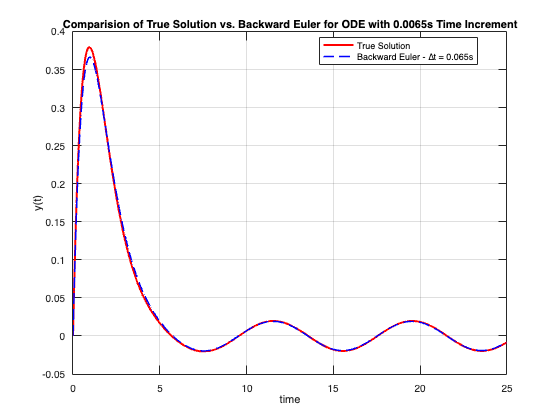


clear all
dT = 0.065; %sec
T = 0:dT:25;

%-----------------------------------------------------------------------------
% write the your code here.
y = zeros(size(T));

A = [   0,     1,    0  ; 
        0,     0,    1  ; 
     -37.5, -61.25, -32];

b = [ 0 ; 0 ; sin( (pi * T(1)) / 4)];

I = eye(size(A));

I_minus_dT_A = I - dT * A;


X_0 = [  0  ;
         1  ;
         0 ];


X_n_array = cell(1, numel(T));
X_n_array{1} = X_0;
y(1) = X_n_array{1}(1);

for n = 1:numel(T)-1
    b = [ 0 ; 0 ; sin( (pi * T(n+1)) / 4)];
    X_n_array{n+1} =  I_minus_dT_A  \ ( X_n_array{n} + dT * b );
    y(n+1) = X_n_array{n+1}(1);

end 


clf;

%------------------------------------------------------------------------------
load('/Users/marc-antoinenadeau/Desktop/4th Semester/ECSE 343/Assignments/A4/q1_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on                                                              
                                                              
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T,y,'b--','LineWidth',1.5,'displayname','Backward Euler - ∆t = 0.065s')

% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------    
xlabel('time')
ylabel('y(t)')
title('Comparision of True Solution vs. Backward Euler for ODE with 0.0065s Time Increment')
grid on
legend("Location","best")

d.  Run the code you wrote in part c again, run the code for $25s$ and use the time step $\Delta t= 1s$.  Plot  $y(t)$ vs $t$ on the same plot as the true solution.

 Is the obtained solution more accurate than the solution in part c? Explain.  **(2 marks)**

*Note: You may copy the code you wrote in part c in the cell below to run it for *$\Delta t =1s$ 

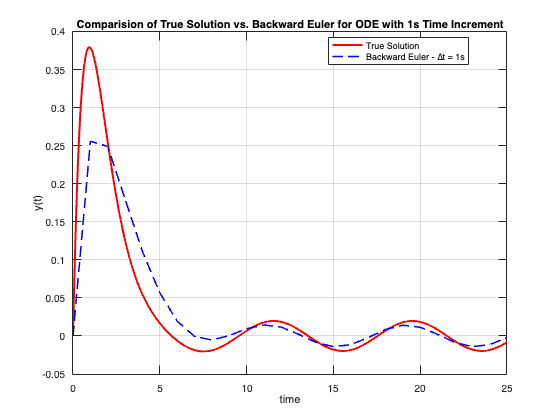

clear all
dT = 1; %sec
T = 0:dT:25; 

%-----------------------------------------------------------------------------
% write the your code here.

y = zeros(size(T));

A = [   0,     1,    0  ; 
        0,     0,    1  ; 
     -37.5, -61.25, -32];

b = [ 0 ; 0 ; sin( (pi * T(1)) / 4)];

I = eye(size(A));

I_minus_dT_A = I - dT * A;


% Keep one


X_0 = [  0  ;
         1  ;
         0 ];


X_n_array = cell(1, numel(T));
X_n_array{1} = X_0;
y(1) = X_n_array{1}(1);

for n = 1:numel(T)-1
    b = [ 0 ; 0 ; sin( (pi * T(n+1)) / 4)];
    X_n_array{n+1} =  I_minus_dT_A  \ ( X_n_array{n} + dT * b );
    y(n+1) = X_n_array{n+1}(1);

end 

%------------------------------------------------------------------------------
load('/Users/marc-antoinenadeau/Desktop/4th Semester/ECSE 343/Assignments/A4/q1_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T,y,'b--','LineWidth',1.5,'displayname','Backward Euler - ∆t = 1s')
% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------                                                              
title('Comparision of True Solution vs. Backward Euler for ODE with 1s Time Increment')                                                            
xlabel('time')
ylabel('y(t)')
grid on
legend("Location","best")

*Here we observe that the approximation of the ODE is not accurate. That is, when time steps are too large,such as in our case when the time steps are 1seconds,  the backward Euler is inacurate. That is, when time steps go from 0.065s to 1s, we see that the solutions y(t) are very different from one another. This is partly because the in our first estimate we used about 384 increments whereas the current on only uses 25. Consequently, the slopes exhibited in c) represent a gross approximation of the true behaviour of the ODE.*

e. For the system of first-order ODEs obtained in part a, use the Forward Euler approximation for the derivative and write the obtained difference Equations below. **(5 marks)**

      
$$\textrm{Note},\textrm{the}\;\textrm{following}\;\textrm{variables}\;\;$$


        $X\left(t_n \right)=\left\lbrack \begin{array}{c}
x_1 \left(t_n \right)\\
x_2 \left(t_n \right)\\
x_3 \left(t_n \right)
\end{array}\right\rbrack \;\;\;$   $X\left(t_{n+1} \right)=\left\lbrack \begin{array}{c}
x_1 \left(t_{n+1} \right)\\
x_2 \left(t_{n+1} \right)\\
x_3 \left(t_{n+1} \right)
\end{array}\right\rbrack$    $A=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-37\ldotp 50 & -61\ldotp 25 & -32
\end{array}\right\rbrack$      $I$ = $\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$     $b\left(t_n \right)=\left\lbrack \begin{array}{c}
0\\
0\\
\sin \left(\frac{\pi t_n }{4}\right)
\end{array}\right\rbrack$   

       
$$\textrm{We}\;\textrm{know}\;\textrm{that}\;\textrm{the}\;\textrm{Forward}\;\textrm{Euler}\;\textrm{Approximation}\;\textrm{can}\;\textrm{be}\;\textrm{expressed}\;\textrm{as}:$$
 

                                                                                          
$$X^{\prime } \left(t_n \right)=\frac{X\left(t_{n+1} \right)-X\left(t_n \right)}{h}\;$$


       
$$\textrm{From}\;\textrm{eq}\ldotp 2,\textrm{we}\;\textrm{know}\;\textrm{that}\;\;X^{\prime } \left(t_n \right)=A\;X\left(t_n \right)+b\left(t_n \right)$$


                                                                       
$$\Rightarrow \frac{X\left(t_{n+1} \right)-X\left(t_n \right)}{h}=A\;X\left(t_n \right)+b\left(t_n \right)$$


                                                                           
$$\;X\left(t_{n+1} \right)-X\left(t_n \right)=h\;A\;X\left(t_n \right)+h\;b\left(t_n \right)\;$$


                                                                                       
$$\;X\left(t_{n+1} \right)=X\left(t_n \right)+h\;A\;X\left(t_n \right)+h\;b\left(t_n \right)\;$$


                                                                                     
$$\;\;X\left(t_{n+1} \right)\;=\left(\;I+h\;A\right)X\left(t_n \right)+$$

$$h\;b\left(t_n \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(\textrm{eq}\ldotp 4\right)$$
 

f. Use the same initial conditions as part c (i.e. $y(0) =0$, $y'(0) =1$, and  $y''(0) = 0$).  Implement the Forward  Euler method to solve the first order ODE's obtained in part a . Run the simulation for $25s$, use the time step $\Delta t= 0.065s$.  Plot  $y(t)$ vs $t$ on the same plot as the true solution, label your plots appropriately. **(5 marks)**

Write your code in the cell below.

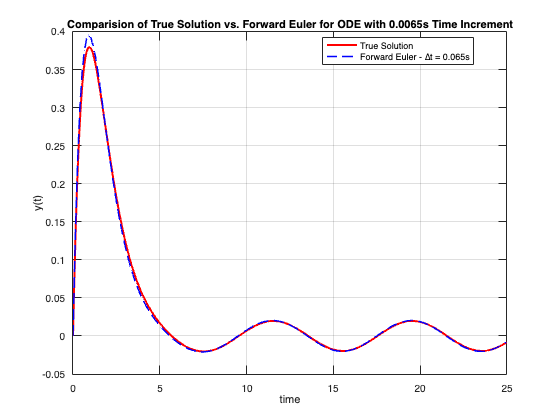

clear all
dT = 0.065; %sec
T = 0:dT:25;

%-----------------------------------------------------------------------------
% write the your code here.

y = zeros(size(T));

A = [   0,     1,    0  ; 
        0,     0,    1  ; 
     -37.5, -61.25, -32];

b = [ 0 ; 0 ; sin( (pi * T(1)) / 4)];

I = eye(size(A));

I_plus_dT_A = I + dT * A;


X_0 = [  0  ;
         1  ;
         0 ];


X_n_array = cell(1, numel(T));
X_n_array{1} = X_0;
y(1) = X_n_array{1}(1);

for n = 1:numel(T)-1
    b = [ 0 ; 0 ; sin( (pi * T(n+1)) / 4)];
    X_n_array{n+1} =  I_plus_dT_A *  X_n_array{n} + dT * b ;
    y(n+1) = X_n_array{n+1}(1);

end 

clf;

%------------------------------------------------------------------------------
load('/Users/marc-antoinenadeau/Desktop/4th Semester/ECSE 343/Assignments/A4/q1_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T,y,'b--','LineWidth',1.5,'displayname','Forward Euler - ∆t = 0.065s')
% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y(t)')
title('Comparision of True Solution vs. Forward Euler for ODE with 0.0065s Time Increment')
grid on
legend("Location","best")

g. Run the code you wrote in part f again, run the code for $25s$ and use the time step $\Delta t= 0.068s$.  Plot  $y(t)$ vs $t$ on the same plot as the true solution.

*Note: You may copy the code you wrote in part f in the cell below to run it for *$\Delta t =0.068s$ 

Comment on the solutions obtained in part e and f. **(2 marks)**

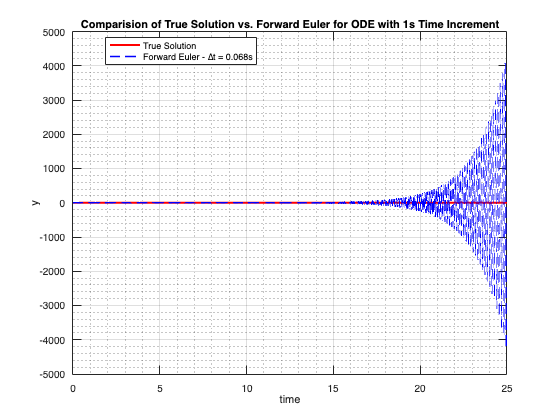

% you may copy the code from part c here and run it for deltaT =1s

clear all
dT = 0.068; %sec
T = 0:dT:25;

%-----------------------------------------------------------------------------
% write the your code here.


y = zeros(size(T));

A = [   0,     1,    0  ; 
        0,     0,    1  ; 
     -37.5, -61.25, -32];

b = [ 0 ; 0 ; sin( (pi * T(1)) / 4)];

I = eye(size(A));

I_plus_dT_A = I + dT * A;


X_0 = [  0  ;
         1  ;
         0 ];


X_n_array = cell(1, numel(T));
X_n_array{1} = X_0;
y(1) = X_n_array{1}(1);

for n = 1:numel(T)-1
    b = [ 0 ; 0 ; sin( (pi * T(n+1)) / 4)];
    X_n_array{n+1} =  I_plus_dT_A *  X_n_array{n} + dT * b ;
    y(n+1) = X_n_array{n+1}(1);

end 

clf;

%------------------------------------------------------------------------------
load('/Users/marc-antoinenadeau/Desktop/4th Semester/ECSE 343/Assignments/A4/q1_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T, y, 'b--', 'LineWidth', 1.5, 'DisplayName', 'Forward Euler - ∆t = 0.068s');


% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y(t)')
title('Comparision of True Solution vs. Forward Euler for ODE with 1s Time Increment')
grid on; grid minor;
legend("Location","best")

*Here we observe the output of the Forward Euler Integration 'explode'. That is, when time steps are too large, the forward euler is not only innacurate but also has a very different qualitative behaviour. Even though the time steps went from 0.065s to 0.068s, we see that the solutions y(t) are very different from one another. That is, in the 0.065s case the approximation closely matches the ODE whereas in the 0.068s case, the solution exhibits a oscillatory divergence behaviour.*

## Question 2 :  

a. Write  steepest descent algorithm to solve  linear system of equations given by  $\textbf A \textbf x = \textbf b$,  where $\textbf A \in \mathbb{R}^{n \times n}$ is a symmetric and positive deifnite matrix, $\textbf b \in \mathbb{R}^{n \times 1}$ and $\textbf x \in \mathbb{R}^{n \times 1}$. You can use the stencil of a function provided in the appendix. (10 marks)

% Write your code in the appendix.

c. In this question, you will solve the matrix systems of size ranging for n= 2, 3, 4 , 5, ..., 100 .  Use the function named *getSystemMatrix_with_lowerConditionNumber* (provided in the appendix) to  generate the system matrix $\textbf A$ and the vector $\textbf b$ of  size n.  The matrix $\textbf A$ generated by the *getSystemMatrix_with_lowerConditionNumber.m* has a good condition number.

Use the LU decomposition based method and the steepest descent method  to compute the solution of linear system with size ranging from n =2  to 100.  Plot the time taken to compute the solution by the LU decompostion based method vs the matrix size. On the same figure, plot the time taken by Steepest Descent method to find the solution.  Label the axes of the plot and include the legend.

Which method takes more time to compute the solution?

Use the cell below to write your code. For measuring  the time taken by each method you can use the code provided in part  b and then change it accordingly.   (8 marks)

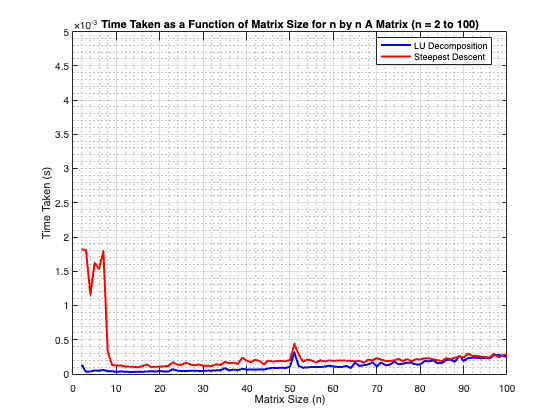

clear all

time_lu = zeros(1, 99); % For sizes 2 to 100
time_sd = zeros(1, 99); % For sizes 2 to 100
iterations = zeros(1, 99);

maxiter = 1000;
tol = 1e-6;

for n = 2:100

    [A, b] = getSystemMatrix_with_lowerConditionNumber(n);
    
    tic;
    lu_decomposition_solver(A, b);
    time_lu(n-1) = toc; 
    
    Xguess = eye(n, 1);

    tic;
    [x_sd, iter] = my_steepest_descent(A, b, Xguess, tol, maxiter);
    time_sd(n-1) = toc;

    iterations(n-1) = iter;

end

% Plotting
clf;
sizes = 2:100;
plot(sizes, time_lu, 'b', 'LineWidth', 2);
hold on;
plot(sizes, time_sd, 'r', 'LineWidth', 2);
hold off; 
xlabel('Matrix Size (n)');
ylabel('Time Taken (s)');
xlim([0,100]); ylim([0,0.005]);
legend('LU Decomposition', 'Steepest Descent', 'Location', 'best');
title('Time Taken as a Function of Matrix Size for n by n A Matrix (n = 2 to 100)');
grid on; grid minor;
hold off;

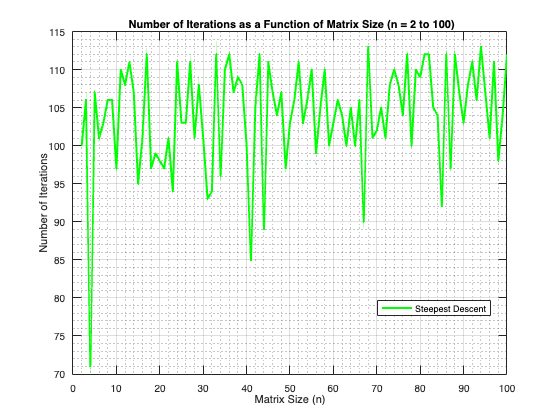


clf;
sizes = 2:100;
plot(sizes, iterations, 'g', 'LineWidth', 2);
xlabel('Matrix Size (n)');
ylabel('Number of Iterations');
legend('Steepest Descent','Location', 'best');
grid on; grid minor;
title(' Number of Iterations as a Function of Matrix Size (n = 2 to 100)');

In Figure 1 of part 2, we observe that for square matrices of size less than 90 with a good condition number, LU decomposition solves the linear problem faster than the steepest descent algorithm. However, when the size becomes above 90, both LU decomposition and steepest descent have a similar time complexity.

*d. *In this part you will repeat part c,  however, this time you need to solve the matrix systems of size ranging from n= 2 to 1000.

Similar to part c, plot the time taken by LU decomposition based solver and the steepest descent for each matrix size. Make sure your plots are properly labeled. On a seperate plot also plot the number of iterations taken by steepest decent vs matrix size.

Compare the plots from part c and d, which method takes more time to compute the solution?

Use the cell below to write your code. (5 marks)

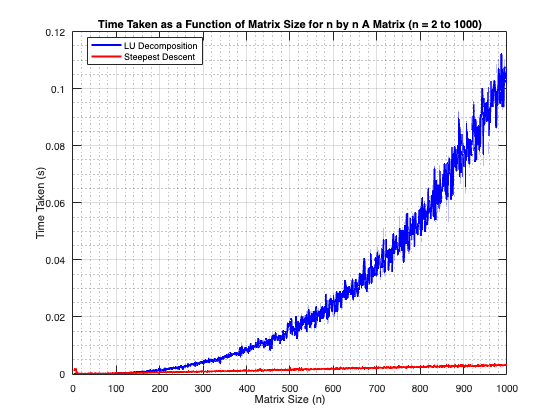

clear all 

time_lu = zeros(1, 999); % For sizes 2 to 100
time_sd = zeros(1, 999); % For sizes 2 to 100
iterations = zeros(1, 999);

maxiter = 1000;
tol = 1e-6;

for n = 2:1000

    [A, b] = getSystemMatrix_with_lowerConditionNumber(n);
    
    tic;
    lu_decomposition_solver(A, b);
    time_lu(n-1) = toc; 
    
    Xguess = eye(n, 1);

    tic;
    [x_sd, iter] = my_steepest_descent(A, b, Xguess, tol, maxiter);
    time_sd(n-1) = toc;

    iterations(n-1) = iter; 

end

% Plotting
clf;
sizes = 2:1000;
plot(sizes, time_lu, 'b', 'LineWidth', 2);
hold on;
plot(sizes, time_sd, 'r', 'LineWidth', 2);
hold off; 
xlabel('Matrix Size (n)');
ylabel('Time Taken (s)');
legend('LU Decomposition', 'Steepest Descent', 'Location', 'best');
title('Time Taken as a Function of Matrix Size for n by n A Matrix (n = 2 to 1000)');
grid on; grid minor;

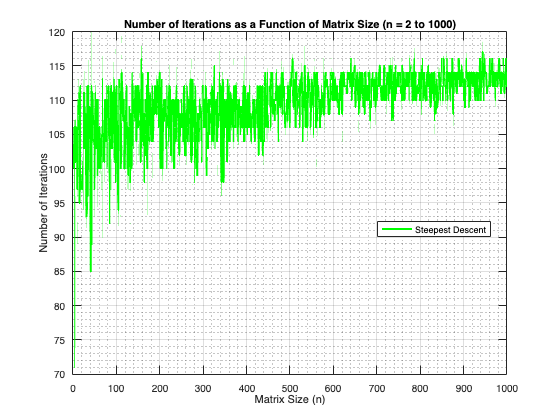


% Plotting
clf;
sizes = 2:1000;
plot(sizes, iterations, 'g', 'LineWidth', 2);
xlabel('Matrix Size (n)');
ylabel('Number of Iterations');
legend('Steepest Descent', 'Location','best');
title('Number of Iterations as a Function of Matrix Size (n = 2 to 1000)');
grid on; grid minor;

As mentioned in part c, for matrices smaller than 90, LU decomposition solves the linear problem faster than steepest descent. Then, from 90 to 100, we observed that LU and steepest descent have similar time complexities. In part d, we expand on this observation and find that when the size exceeds 100, steepest descent is much more effective than LU decomposition at solving the linear problem. In fact, LU's time complexity grows exponentially, whereas that of steepest descent grows linearly where solving the system requires roughly 100 iterations. As such, for large matrices, steepest descent is a much more effective option.

e. Similar to the previous part*, *you need to solve the matrix systems of size ranging from n= 2 to 1000.  

Instead this time you will use the function *getSystemMatrix_with_higherConditionNumber *to generate the system matrix $\textbf A$* and vector *$\textbf b$*. T*he function is provided in the appendix. The function, *getSystemMatrix_with_higherConditionNumber, * generates the system matrix $\textbf A$  which has a slightly higher condition number than the matrix you used in parts c and d.

Plot the time taken by LU  decomposition based solver and the steepest descent for each matrix size. Also plot the number of iterations taken by steepest decent vs matrix size.

Comment on the similarities and difference between the  plots from part d and e.

You can use the cell below to write your code. (5 marks)

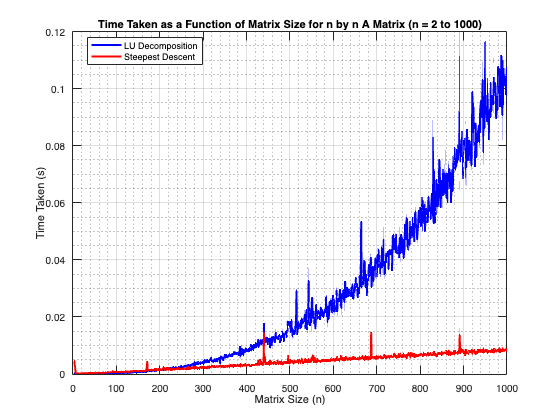



clear all

time_lu = zeros(1, 999); % For sizes 2 to 100
time_sd = zeros(1, 999); % For sizes 2 to 100
iterations = zeros(1, 999);

maxiter = 1000;
tol = 1e-6;

for n = 2:1000

    [A, b] = getSystemMatrix_with_higherConditionNumber(n);
    
    tic;
    lu_decomposition_solver(A, b);
    time_lu(n-1) = toc; 
    
    Xguess = eye(n, 1);

    tic;
    [x_sd, iter] = my_steepest_descent(A, b, Xguess, tol, maxiter);
    time_sd(n-1) = toc;

    iterations(n-1) = iter; 

end


% Plotting
clf;
sizes = 2:1000;
plot(sizes, time_lu, 'b', 'LineWidth', 2);
hold on;
plot(sizes, time_sd, 'r', 'LineWidth', 2);
hold off; 
grid on; grid minor;
xlabel('Matrix Size (n)');
ylabel('Time Taken (s)');
legend('LU Decomposition', 'Steepest Descent', 'Location', 'best');
title('Time Taken as a Function of Matrix Size for n by n A Matrix (n = 2 to 1000)');
hold off;

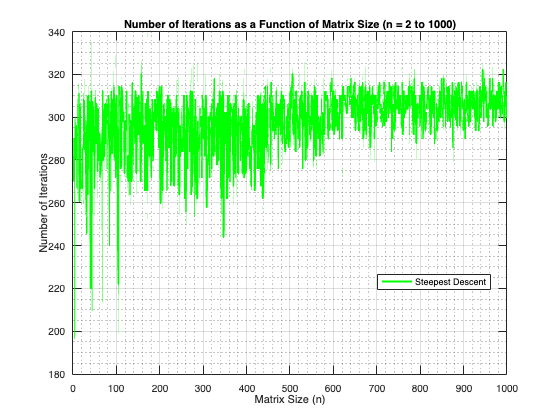



clf;
sizes = 2:1000;
plot(sizes, iterations, 'g', 'LineWidth', 2);
xlabel('Matrix Size (n)');
ylabel('Number of Iterations');
legend('Steepest Descent', 'location', 'best');
grid on; grid minor;
title('Number of Iterations as a Function of Matrix Size (n = 2 to 1000)');

In part d, we observed that for matrices with a good condition number smaller than 90, LU decomposition solves the linear problem faster than steepest descent. Then, from 90 to 100, we observed that LU and steepest descent have similar time complexities. When the size exceeds 100, steepest descent is much more effective than LU decomposition at solving the linear problem. However, we now observe that when solving matrices with bad condition numbers, the time complexities of LU decomposition remain unchanged from part d to e, but the time complexity of the steepest descent algorithm grows more quickly. Namely, the slope is about three times as steep. This can be observed by comparing the number of iterations for solving it in part d as opposed to e. We observe that in part d, we needed about 100 iterations, whereas now we need 300. The consequence of this is that LU decomposition is quicker for matrices smaller than 200 (i.e., both time complexities cross at size 200). In other words, badly conditioned matrices extend the range where LU is a more effective choice compared to gradient descent, but regardless, steepest descent wins in the long run as it is linear.

## Appendix 

function [A,b]= getSystemMatrix_with_lowerConditionNumber(n)
%  n is the size of the matrix .
% outputs: A square matrix of size n times n
%          b  vector of size n.

    rng(0);
    density =10/n;
    R = sprand(n,n,density,0.25);
    A= R'*R;
    b = rand(n,1);
end

function [A,b]= getSystemMatrix_with_higherConditionNumber(n)
% n is the size of the matrix .
% outputs: A square matrix of size n times n
%          b  vector of size n.

    rng(0);
    density =10/n;
    R = sprand(n,n,density,0.15);
    A= R'*R;
    b = rand(n,1);
end

Write your steepest descent here.

function [x, iter] = my_steepest_descent(A, b, Xguess, tol, maxiter)
% inputs:
%          A-       a symmeteric and positive definite matrix.
%          b :      RHS vector
%          Xguess:  Initial guess 
%          tol:     tolerance 
%          maxiter: maximum iterations 

%outputs:  x:       solution of the system Ax =b
%          iter:    number of iterations it took to converge


    x = Xguess;
    r = b - A * x;
    iter = 0;
    while norm(r) > tol && iter < maxiter
        
       alpha = (r' * r) / (r' * A * r);
       x = x + alpha * r;
       r = b - A * x;
       iter = iter + 1;
    end
end

function x = lu_decomposition_solver(A,b)
       
    [L,U,P] = lu(A);
    x = U \ (L \ (P * b));

end 